## Task 1

%1.b. 
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = [1500, 1600, 1700, 1800, 1900];  % Values for packet rate in pps
f = 1000000;                              % Queue size(in bytes)
b = 10^-4;                                % Bit Error Rate

N = 20;                                   % number of simulation

pkt_delay = zeros(1, length(lambda));
error_delay = zeros(1, length(lambda));
pkt_loss = zeros(1,length(lambda));
error_loss = zeros(1,length(lambda));

for i = 1:length(lambda)

    PL = zeros(1, N);
    APD = zeros(1, N);
    MPD = zeros(1, N);
    TT = zeros(1, N);
    
    for j = 1:N
        [PL(j), APD(j), MPD(j), TT(j)] = Simulator2(lambda(i), C, f, P, b);
    end

    alfa = 0.1; % 90% confidence interval

    AVERAGE = mean(PL);
    TERM = norminv(1-alfa/2)*sqrt(var(PL)/N);
    fprintf("Packet Loss (%%)       = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss(i) = AVERAGE;
    error_loss(i) = TERM;

    AVERAGE = mean(APD);
    TERM = norminv(1-alfa/2)*sqrt(var(APD)/N);
    fprintf("Av. Packet Delay (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay(i) = AVERAGE;
    error_delay(i) = TERM;

end

Packet Loss (%)       = 3.28e+01 +- 4.13e-02


Av. Packet Delay (ms)  = 1.67e+00 +- 1.20e-02


Packet Loss (%)       = 3.28e+01 +- 4.92e-02


Av. Packet Delay (ms)  = 2.11e+00 +- 1.18e-02


Packet Loss (%)       = 3.28e+01 +- 3.91e-02


Av. Packet Delay (ms)  = 2.82e+00 +- 2.36e-02


Packet Loss (%)       = 3.28e+01 +- 3.34e-02


Av. Packet Delay (ms)  = 4.22e+00 +- 5.41e-02


Packet Loss (%)       = 3.28e+01 +- 5.22e-02


Av. Packet Delay (ms)  = 7.96e+00 +- 3.05e-01


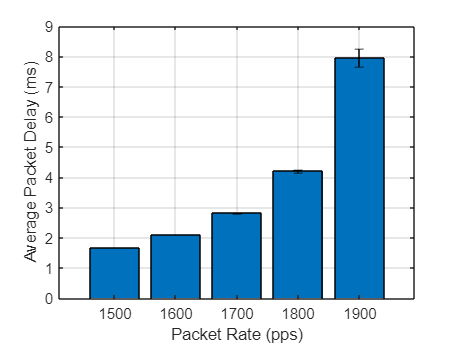


figure(1)
bar(categorical(lambda), pkt_delay)
xlabel("Packet Rate (pps)")
ylabel("Average Packet Delay (ms)")
hold on
er = errorbar(categorical(lambda), pkt_delay, error_delay, error_delay);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

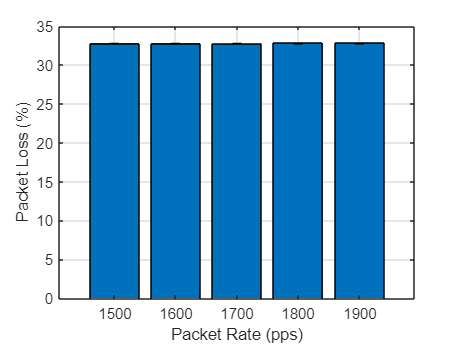


%%% Plot the results
figure(2)
bar(categorical(lambda), pkt_loss)
xlabel("Packet Rate (pps)")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(lambda), pkt_loss, error_loss, error_loss);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

fprintf("-------------------------------------------")

-------------------------------------------

%% conclusão: Verifica-se que, quanto menor é BER, menor é a perda de pacotes comparando com
% alinea 1.a.